TODO:

- Use visualizaiton formatting from previous delta plots for hyper-redux fields

- Visualize ANN architecture

- Explicitly list equation that is solved for

clear; close all; clc;
addpath('functions');
addpath('visualization');

% toggles
sweepHDM = false;
debug    = false;

% grid initialization
Nx = 75;
Ny = 75;
dx = 1 / (Nx-1);
dy = 1 / (Ny-1);
N  = Nx * Ny;

% idx = @(i,j) (j-1) * Nx + i;

x_values = linspace(0, 1, Nx);
y_values  = linspace(0, 1, Ny);

% nonlinearity constants
alpha = 3e-2; % K^-1
T_ref = 300;    % K

% enforcing Dirichlet profile (x = 0)
T_D = @(y, y_bar) (300 .* (y < 1/3) ...
                 + (300 + 325 * (sin(3 * pi * abs(y - y_bar)) + 1)) .* (y >= 1/3 & y <= 2/3) ...
                 + (300 .* (y > 2/3)));

## Part 1: Computing the Candidate Parameter Points

rng(53);
disp("Building parameter domain...")

Building parameter domain...



% parameter domain D = [0, 0.5] x [5e-3, 0.025] x [0.4, 0.6]
pts   = 10;
U     = linspace(0.1, 0.6, pts);
kappa = linspace(5e-3, 0.025, pts);
y_bar = linspace(0.4, 0.6, pts);

[P1, P2, P3] = ndgrid(U, kappa, y_bar);
mu   = [P1(:), P2(:), P3(:)];
N_mu = size(mu, 1);
disp("Done.")

Done.



if sweepHDM
    disp("___________________________________________________________________")
    disp("Recomputing HDM solutions for ROM construction.")

    fprintf("Number of candidate parameters: %d\n", N_mu);
    fprintf("Pe range: [0, %.1f]\n", max(mu(:,1)) / min(mu(:,2)));
    disp("First 10 parameter triples for inspection:")
    disp(mu(1:min(10, N_mu), :))
    disp("Computing and storing solutions...")

    nx_int = Nx - 2;
    ny_int = Ny - 2;
    nDOF   = nx_int * ny_int;

    w         = zeros(nDOF, N_mu);
    iters_all = zeros(N_mu, 1);
    res_all   = zeros(N_mu, 1);
    failed    = false(N_mu, 1);

    tic;

    epsilon = 1e-6;
    max_iter = 200;
    for k = 1:N_mu
        mu_k = mu(k, :);
        [w(:,k), iters_all(k), residual] = computeNonLinearHDM(Nx, Ny, dx, dy, T_D, y_values, mu_k, alpha, T_ref, epsilon, max_iter);
        res_all(k) = residual(end);
        failed(k)  = residual(end) >= 1e-6;

        if mod(k, 100) == 0
            fprintf('  %4d / %4d  (%5.1f s elapsed)  failures so far: %3d\n', ...
                k, N_mu, toc, sum(failed(1:k)));
        end
    end
    time_HDM = toc;

    fprintf('HDM construction time: %.4f seconds\n', time_HDM);
    fprintf('Converged: %d / %d\n', N_mu - sum(failed), N_mu);

    save('mu_nonlinear.mat',   'mu');
    save('w_nonlinear.mat',    'w', '-v7.3');
    save('meta_nonlinear.mat', 'time_HDM', 'iters_all', 'res_all', 'failed', 'alpha', 'T_ref');
end

load('mu_nonlinear.mat');
load('w_nonlinear.mat');
if exist('meta_nonlinear.mat', 'file')
    load('meta_nonlinear.mat');
else
    time_HDM = NaN;
end

t_hdm_per_solve = time_HDM / N_mu;   % avg HDM cost per solve
fprintf('HDM cost per solve: %.4f s\n', t_hdm_per_solve);

HDM cost per solve: 0.1231 s


## Part 2: Buidling Linear PROM Using Random (Latin Hypercube) Sampling of Snapshots

Linear Galerkin PROM is insufficient for modeling non-linear system. A snapshot Budget Sweep is conducted to demonstrate the Kolmogorov Barrier and find baseline accuracy and computation.

% N_cand   = 10;
% N_repeat = 20;
% N_mu     = size(mu, 1);
% 
% E_max = zeros(N_repeat, 1);
% E_avg = zeros(N_repeat, 1);
% 
% for r = 1:N_repeat
%     fprintf('Building LHS snapshot set (%2.0f)...\n', r);
% 
%     tic;
%     lhs       = lhsdesign(N_cand, 3);
%     U_lhs     = 0.1  + lhs(:,1) * (0.5  - 0.1);
%     kappa_lhs = 5e-3 + lhs(:,2) * (0.025 - 5e-3);
%     y_bar_lhs = 0.4  + lhs(:,3) * (0.6  - 0.4);
%     mu_lhs    = [U_lhs, kappa_lhs, y_bar_lhs];
% 
%     w_lhs   = zeros(size(w, 1), N_cand);
%     idx_lhs = zeros(N_cand, 1);
%     for j = 1:N_cand
%         [~, idx_min] = min(vecnorm(mu - mu_lhs(j,:), 2, 2));
%         idx_lhs(j)   = idx_min;
%         w_lhs(:,j)   = w(:, idx_min);
%     end
% 
%     V = buildBasisPOD(w_lhs, debug);
%     if r == 1
%         t_offline_affine = toc;
%     end
% 
%     idx_test = setdiff(1:N_mu, idx_lhs);
%     mu_test  = mu(idx_test, :);
%     w_test   = w(:, idx_test);
% 
%     w_r = zeros(size(w_test));
%     tic;
%     for j = 1:length(idx_test)
%         [A, b]     = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, mu_test(j,:));
%         [A_r, b_r] = assembleROM(A, b, V);
%         w_r(:,j)   = computeROM(A_r, b_r, V);
%     end
%     t_online_affine = toc;
% 
%     errors   = computeErrors(w_test, w_r);
%     E_max(r) = max(errors);
%     E_avg(r) = mean(errors);
% end

% fprintf('Visualizing ROM delta for final snapshot set (LHS sampling)...\n');
% j_vis = 1;
% T_hdm = reshapeSolution(w_test(:,j_vis), Nx, Ny, T_D, y_values, mu_test(j_vis,:));
% T_rom = reshapeSolution(w_r(:,j_vis),    Nx, Ny, T_D, y_values, mu_test(j_vis,:));
% 
% plotSolution(T_hdm, mu_test(j_vis,:), false);
% plotSolution(T_rom - T_hdm, mu_test(j_vis,:), true);
% plotSolution(T_rom, mu_test(j_vis,:), false);
% 
% E_max_lhs_mean  = mean(E_max);
% E_avg_lhs_mean  = mean(E_avg);
% E_max_lhs_stdev = std(E_max);
% E_avg_lhs_stdev = std(E_avg);
% 
% fprintf('==================================================================\n');
% fprintf('LHS sampling result (%d snapshot sets, %d snapshots each):\n', N_repeat, N_cand);
% fprintf('E_max = %.4f +/- %.4f\n', E_max_lhs_mean, E_max_lhs_stdev);
% fprintf('E_avg = %.4f +/- %.4f\n', E_avg_lhs_mean, E_avg_lhs_stdev);
% fprintf('==================================================================\n');

fprintf('==================================================================\n');

fprintf('Part 2: Linear PROM — Snapshot Budget Sweep\n');

Part 2: Linear PROM — Snapshot Budget Sweep


fprintf('==================================================================\n');


N_mu     = size(mu, 1);

nx_int = Nx - 2;
ny_int = Ny - 2;
N_int  = nx_int * ny_int;

fprintf('\n%-6s  %-12s  %-12s  %-12s  %-12s  %-10s\n', ...
    'k', 'E_avg', 'E_max', 't_offline(s)', 't_online(s)', 'rcond');


k       E_avg         E_max         t_offline(s)  t_online(s)   rcond     



e_avg_hist = nan(50, 1);
e_max_hist = nan(50, 1);
k_plateau  = NaN;

rng(42);
for k_test = 1:50

    % draw k_test LHS snapshots
    lhs_k    = lhsdesign(k_test, 3);
    U_k      = 0.1  + lhs_k(:,1) * (0.6   - 0.1);
    kappa_k  = 5e-3 + lhs_k(:,2) * (0.025 - 5e-3);
    y_bar_k  = 0.4  + lhs_k(:,3) * (0.6   - 0.4);
    mu_lhs_k = [U_k, kappa_k, y_bar_k];

    % snap to nearest grid point + build basis
    w_lhs_k   = zeros(N_int, k_test);
    idx_lhs_k = zeros(k_test, 1);
    tic;
    for j = 1:k_test
        [~, idx_min] = min(vecnorm(mu - mu_lhs_k(j,:), 2, 2));
        idx_lhs_k(j) = idx_min;
        w_lhs_k(:,j) = w(:, idx_min);
    end
    V_k = buildBasisPOD(w_lhs_k, false);
    t_basis = toc;

    % total offline = HDM solves + basis construction
    t_offline_k = k_test * t_hdm_per_solve + t_basis;

    % check condition of reduced operator
    [A_check, ~] = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, mu(1,:));
    A_r_check    = V_k' * A_check * V_k;
    rc           = rcond(A_r_check);

    if rc < 1e-12
        fprintf('%-6d  SINGULAR (rcond = %.2e) — stopping\n', k_test, rc);
        k_plateau = k_test - 1;
        break;
    end

    % test set
    idx_test_k = setdiff(1:N_mu, idx_lhs_k);
    mu_test_k  = mu(idx_test_k, :);
    w_test_k   = w(:, idx_test_k);

    % online evaluation
    w_r_k = zeros(N_int, length(idx_test_k));
    tic;
    for j = 1:length(idx_test_k)
        [A_k, b_k]     = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, mu_test_k(j,:));
        [A_r_k, b_r_k] = assembleROM(A_k, b_k, V_k);
        w_r_k(:,j)     = computeROM(A_r_k, b_r_k, V_k);
    end
    t_online_k = toc;

    errs               = computeErrors(w_test_k, w_r_k);
    e_avg_hist(k_test) = mean(errs);
    e_max_hist(k_test) = max(errs);

    fprintf('%-6d  %-12.4f  %-12.4f  %-12.4f  %-12.4f  %-10.2e\n', ...
        k_test, e_avg_hist(k_test), e_max_hist(k_test), t_offline_k, t_online_k, rc);
end

1       0.0427        0.1360        0.1238        0.2680        1.00e+00  
2       0.0335        0.1282        0.2467        0.2623        5.80e-02  
3       0.0320        0.1269        0.3698        0.2889        3.62e-02  
4       0.0423        0.0850        0.4930        0.2739        3.20e-02  
5       0.1060        0.2924        0.6163        0.3139        1.84e-02  
6       0.1527        0.4577        0.7395        0.3233        7.15e-03  
7       0.1341        0.2275        0.8628        0.3369        6.13e-03  
8       0.1494        0.3527        0.9858        0.3361        3.96e-03  
9       0.1270        0.1924        1.1096        0.3553        5.78e-03  
10      0.1294        0.2104        1.2331        0.3707        2.85e-03  
11      0.1247        0.1910        1.3559        0.4020        2.63e-03  
12      0.1253        0.1942        1.4794        0.4046        2.22e-03  
13      0.1245        0.1931        1.6018        0.4117        1.50e-03  
14      0.1330        0.2

24      SINGULAR (rcond = 1.12e-15) — stopping



% record timing and errors at saturation k
lhs_k    = lhsdesign(k_plateau, 3);
U_k      = 0.1  + lhs_k(:,1) * (0.6   - 0.1);
kappa_k  = 5e-3 + lhs_k(:,2) * (0.025 - 5e-3);
y_bar_k  = 0.4  + lhs_k(:,3) * (0.6   - 0.4);
mu_lhs_k = [U_k, kappa_k, y_bar_k];

w_lhs_k   = zeros(N_int, k_plateau);
idx_lhs_k = zeros(k_plateau, 1);
tic;
for j = 1:k_plateau
    [~, idx_min] = min(vecnorm(mu - mu_lhs_k(j,:), 2, 2));
    idx_lhs_k(j) = idx_min;
    w_lhs_k(:,j) = w(:, idx_min);
end
V = buildBasisPOD(w_lhs_k, false);
t_offline_affine = toc + (k_plateau * t_hdm_per_solve);

idx_test = setdiff(1:N_mu, idx_lhs_k);
mu_test  = mu(idx_test, :);
w_test   = w(:, idx_test);

w_r = zeros(N_int, length(idx_test));
tic;
for j = 1:length(idx_test)
    [A, b]     = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, mu_test(j,:));
    [A_r, b_r] = assembleROM(A, b, V);
    w_r(:,j)   = computeROM(A_r, b_r, V);
end
t_online_affine = toc;

errors_affine = computeErrors(w_test, w_r);
E_max_affine  = max(errors_affine);
E_avg_affine  = mean(errors_affine);
E_std_affine  = std(errors_affine);

fprintf('\n==================================================================\n');

fprintf('Linear PROM at saturation (k = %d snapshots):\n', k_plateau);

Linear PROM at saturation (k = 23 snapshots):


fprintf('E_avg        = %.4f +/- %.4f\n', E_avg_affine, E_std_affine);

E_avg        = 0.1285 +/- 0.0514


fprintf('E_max        = %.4f\n', E_max_affine);

E_max        = 0.2137


fprintf('t_offline    = %.4f s\n', t_offline_affine);

t_offline    = 2.8352 s


fprintf('t_online     = %.4f s\n', t_online_affine);

t_online     = 0.5745 s


fprintf('==================================================================\n');

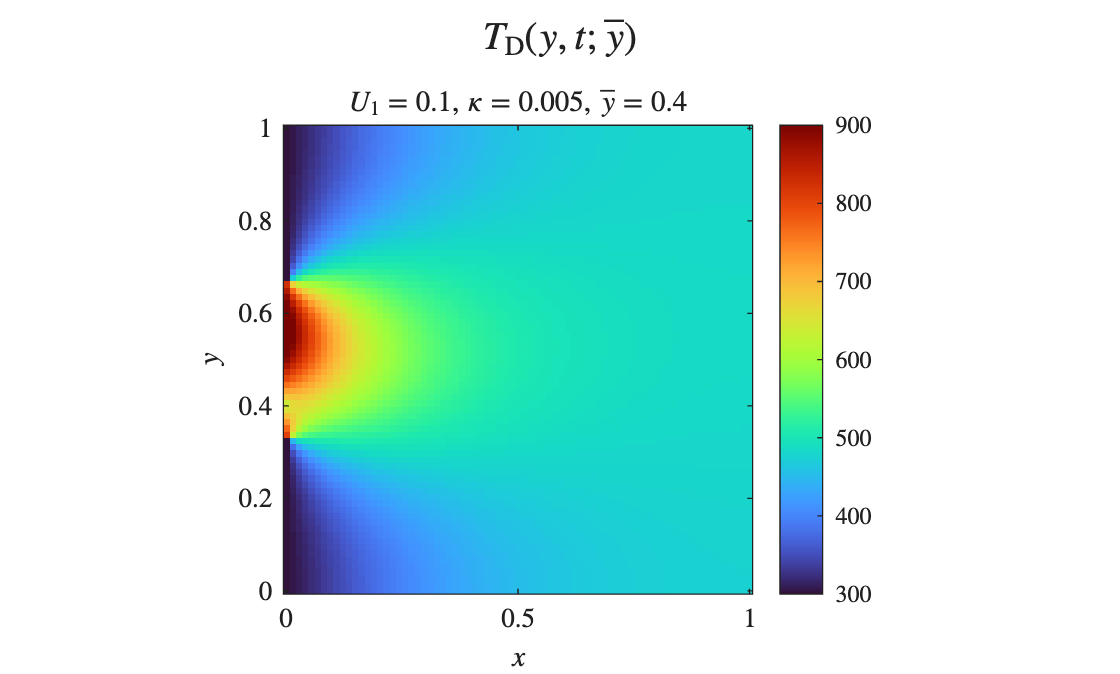


% visualize one test case
j_vis = 1;
T_hdm = reshapeSolution(w_test(:,j_vis),     Nx, Ny, T_D, y_values, mu_test(j_vis,:));
T_rom = reshapeSolution(w_r(:,j_vis),        Nx, Ny, T_D, y_values, mu_test(j_vis,:));
plotSolution(T_hdm,          mu_test(j_vis,:), false);

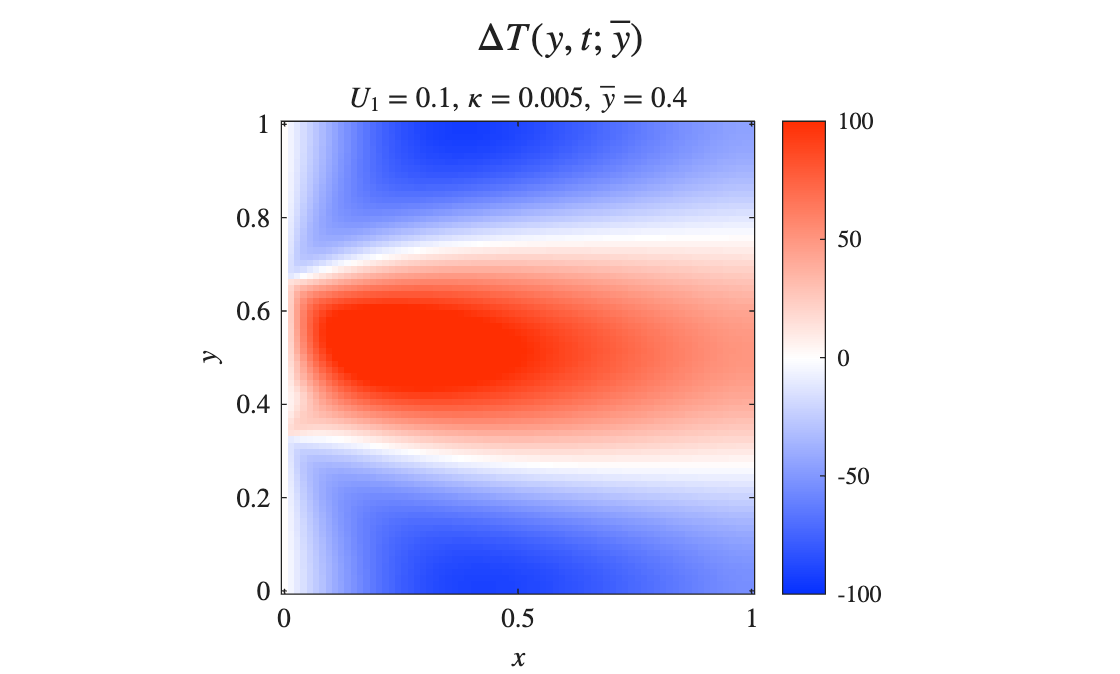

plotSolution(T_rom - T_hdm,  mu_test(j_vis,:), true);

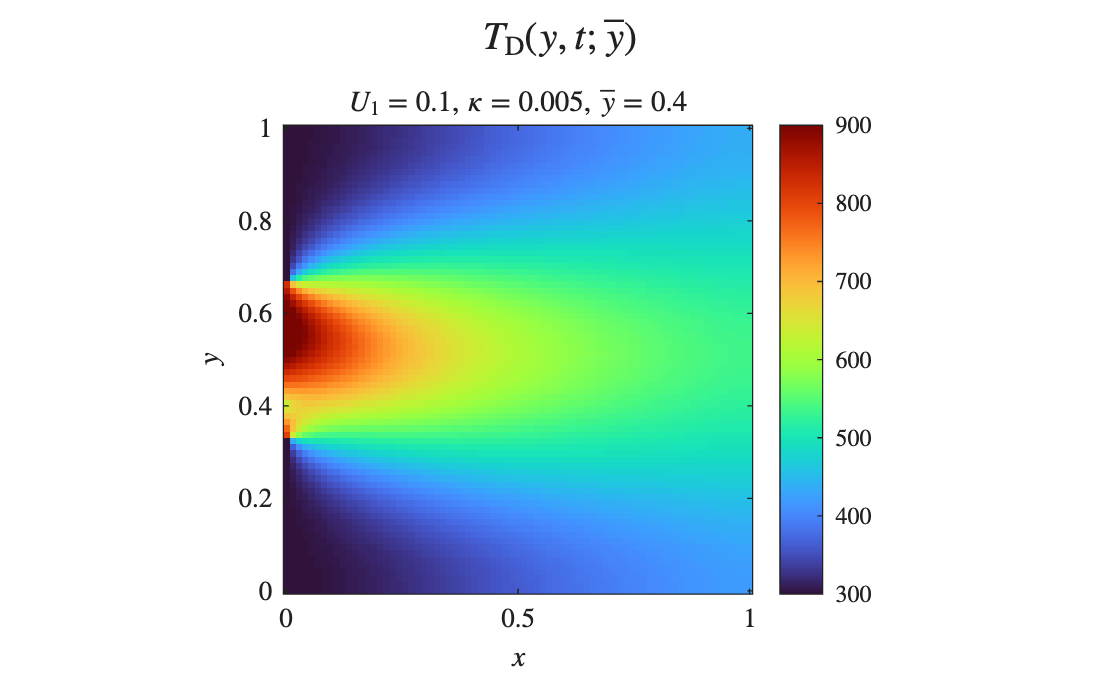

plotSolution(T_rom,          mu_test(j_vis,:), false);

## Part 3: DEIM Hyperreduction of Non-Linear Diffusivity

% new snapshot basis (independent from Part 2)

N_snap = 10;
rng(42);
lhs     = lhsdesign(N_snap, 3);
U       = 0.1  + lhs(:,1) * (0.6   - 0.1);
kappa0   = 5e-3 + lhs(:,2) * (0.025 - 5e-3);
y_bar   = 0.4  + lhs(:,3) * (0.6   - 0.4);
mu_lhs  = [U, kappa0, y_bar];

w_lhs   = zeros(N_int, N_snap);
idx_lhs = zeros(N_snap, 1);
for j = 1:N_snap
    [~, idx_min]    = min(vecnorm(mu - mu_lhs(j,:), 2, 2));
    idx_lhs(j) = idx_min;
    w_lhs(:,j) = w(:, idx_min);
end
V = buildBasisPOD(w_lhs, false);

idx_test = setdiff(1:N_mu, idx_lhs);
mu_test  = mu(idx_test, :);
w_test   = w(:, idx_test);
w_test_hdm = w_test;

% params
k_f = 4;    % upper limit of DEIM POD modes

fprintf('==================================================================\n');

fprintf('Part 3: DEIM Hyperreduction\n');

Part 3: DEIM Hyperreduction


fprintf('==================================================================\n');


% collecting nonlinear (kappa) snapshots
fprintf('Collecting nonlinear kappa snapshots...\n');


nx_int = Nx - 2;
ny_int = Ny - 2;
N_int  = nx_int * ny_int;

tic;
f_snap = zeros(N_int, N_snap);
for k = 1:N_snap
    f_snap(:, k) = computeNonLinearKappa(w(:,k), mu(k,2), alpha, T_ref);
end

fprintf('Nonlinear snapshots collected: [%d x %d]\n', size(f_snap,1), size(f_snap,2));

Nonlinear snapshots collected: [5329 x 10]


fprintf('kappa range across all snapshots: [%.4f, %.4f]\n', min(f_snap(:)), max(f_snap(:)));

kappa range across all snapshots: [0.0051, 0.0993]



%% Step 2 — Build DEIM basis V_f
fprintf('\nBuilding DEIM basis V_f...\n');


Building DEIM basis V_f...



epsilon_deim = 1e-4;
V_f = buildBasisPOD(f_snap, true);


ROB V built using POD with size [5329 x 10] = [N x N_snapshots].
Checking if V'V = I...Success!
___________________________________________________________________

V_f = V_f(:, 1:k_f);

fprintf('DEIM basis size: k_f = %d\n', k_f);

DEIM basis size: k_f = 4



fprintf('\nRunning greedy DEIM algorithm...\n');


Running greedy DEIM algorithm...


[P, I_deim] = buildMaskDEIM(V_f, true);


DEIM interpolation indices selected: k_f = 4
Indices: 42 1280 4199 2336 
condition number of P'*V_f: 2.44e+00
P'*V_f is well-conditioned.


fprintf('DEIM indices selected: %s\n', mat2str(I_deim'));

DEIM indices selected: [42 1280 4199 2336]



% DEIM projection operator (1 or 0)
Pi_f = V_f / (P' * V_f);   % N_int x k_f

t_offline_deim = toc + (N_snap * t_hdm_per_solve);
fprintf('DEIM offline completed in %.4f seconds.\n', t_offline_deim);

DEIM offline completed in 1.2437 seconds.



fprintf('Pi_f size: [%d x %d]\n', size(Pi_f,1), size(Pi_f,2));

Pi_f size: [5329 x 4]



% precomputed linear operator and BC vector
%  (these don't depend on kappa so they never change across Picard iters)
[A_lin, b_lin] = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, [mu(1,1), 1.0, mu(1,3)]);
% note kappa=1.0 placeholder 
% we extract only the structural sparsity pattern here

% evaluate DEIM-HPROM at all test parameter points
fprintf('\nEvaluating DEIM-HPROM on test parameter set (LHS)...\n');


Evaluating DEIM-HPROM on test parameter set (LHS)...



% reuse same LHS training/test split from part 2 (final iter)
% recall idx_test and mu_test already defined from Part 2
N_test   = length(idx_test);
w_r_deim = zeros(N_int, N_test);

Running the HPROM (Hyperreduced PROM): 

- Looping `f_I = computeNonLinearKappa(w_j(I_deim), ...)` evaluates κ (diffusion) at just 1 or 2 spatial locations, and `kappa_vec = Pi_f * f_I` reconstructs the full `N_int`�–dimensional κ field from only those 2 values.

tic;
for j = 1:N_test
    if mod(j, 100) == 0
        fprintf('  %4d / %4d\n', j, N_test);
    end

    mu_j = mu_test(j,:);

    % warm start: cheap affine ROM solve
    [A0, b0]   = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, mu_j);
    [A_r, b_r] = assembleROM(A0, b0, V);
    w_j        = computeROM(A_r, b_r, V);   % already full N_int x 1

    % evaluate kappa at DEIM indices only
    f = computeNonLinearKappa(w_j(I_deim), mu_j(2), alpha, T_ref);

    % reconstruct full kappa field
    kappa_vec = Pi_f * f;

    % clamp to physical range
    kappa_vec = max(kappa_vec, mu_j(2) * 0.5);

    % mean-field effective kappa
    kappa_eff = mean(kappa_vec);
    mu_eff    = [mu_j(1), kappa_eff, mu_j(3)];

    % final reduced solve with corrected kappa
    [A_eff, b_eff] = assembleLinearSystem(Nx, Ny, dx, dy, T_D, y_values, mu_eff);
    [A_r_eff, b_r_eff] = assembleROM(A_eff, b_eff, V);
    w_r_deim(:, j) = computeROM(A_r_eff, b_r_eff, V);
end

   100 /  990
   200 /  990
   300 /  990
   400 /  990
   500 /  990
   600 /  990
   700 /  990
   800 /  990
   900 /  990


t_online_deim = toc;
fprintf('DEIM online completed in %.4f seconds for %d test points.\n', t_online_deim, N_test);

DEIM online completed in 0.8463 seconds for 990 test points.



% errors
errors_deim = computeErrors(w_test, w_r_deim);
E_max_deim  = max(errors_deim);
E_avg_deim  = mean(errors_deim);

fprintf('\n==================================================================\n');

fprintf('DEIM-HPROM results (%d test points):\n', N_test);

DEIM-HPROM results (990 test points):


fprintf('E_max = %.4f\n', E_max_deim);

E_max = 0.0626


fprintf('E_avg = %.4f\n', E_avg_deim);

E_avg = 0.0118



% vis test case
fprintf('Visualizing DEIM-HPROM delta for test point 1...\n');

Visualizing DEIM-HPROM delta for test point 1...


j_vis    = 1;
T_hdm_v  = reshapeSolution(w_test(:,j_vis),      Nx, Ny, T_D, y_values, mu_test(j_vis,:));
T_deim_v = reshapeSolution(w_r_deim(:,j_vis),    Nx, Ny, T_D, y_values, mu_test(j_vis,:));

plotSolution(T_hdm_v,             mu_test(j_vis,:), false);

plotSolution(T_deim_v - T_hdm_v,  mu_test(j_vis,:), true);

plotSolution(T_deim_v,            mu_test(j_vis,:), false);


% compare affine ROM vs. DEIM-HPROM
fprintf('\n==================================================================\n');

fprintf('Comparison: Affine ROM vs DEIM-HPROM\n');

Comparison: Affine ROM vs DEIM-HPROM


fprintf('%-20s  %-10s  %-10s\n', 'Method', 'E_max', 'E_avg');

Method                E_max       E_avg     


fprintf('%-20s  %-10.4f  %-10.4f\n', 'Affine ROM (LHS)',  E_max_affine, E_avg_affine);

Affine ROM (LHS)      0.2137      0.1285    


fprintf('%-20s  %-10.4f  %-10.4f\n', 'DEIM-HPROM',        E_max_deim,     E_avg_deim);

DEIM-HPROM            0.0626      0.0118    


## Part 4: ANN-Augmented PMOR

fprintf('==================================================================\n');

fprintf('Part 4: ANN-Augmented PMOR\n');

Part 4: ANN-Augmented PMOR



% build full SVD of all snapshots to see energy distribution
fprintf('Computing full POD energy spectrum...\n');

Computing full POD energy spectrum...



w_ref = mean(w, 2);   % reference state: mean snapshot
W_centered = w - w_ref;

R = W_centered' * W_centered;
[phi, lambda] = eig(R);
[lambda_sorted, idx] = sort(diag(lambda), 'descend');
phi_sorted = phi(:, idx);

V_full = W_centered * phi_sorted;
for i = 1:size(V_full, 2)
    V_full(:,i) = V_full(:,i) / norm(V_full(:,i));
end

E_POD = 1 - cumsum(lambda_sorted) / sum(lambda_sorted);

% print energy table for first 30 modes
fprintf('\nMode  |  Energy retained (1 - E_POD)\n');


Mode  |  Energy retained (1 - E_POD)


fprintf('------|------------------------------\n');

------|------------------------------


for i = 1:min(30, length(lambda_sorted))
    fprintf('  %3d |  %.8f  (truncation error: %.2e)\n', i, 1-E_POD(i), E_POD(i));
end

    1 |  0.61542047  (truncation error: 3.85e-01)
    2 |  0.92388612  (truncation error: 7.61e-02)
    3 |  0.98569471  (truncation error: 1.43e-02)
    4 |  0.99371228  (truncation error: 6.29e-03)
    5 |  0.99684290  (truncation error: 3.16e-03)
    6 |  0.99878736  (truncation error: 1.21e-03)
    7 |  0.99945231  (truncation error: 5.48e-04)
    8 |  0.99963683  (truncation error: 3.63e-04)
    9 |  0.99975713  (truncation error: 2.43e-04)
   10 |  0.99985352  (truncation error: 1.46e-04)
   11 |  0.99992030  (truncation error: 7.97e-05)
   12 |  0.99996491  (truncation error: 3.51e-05)
   13 |  0.99998032  (truncation error: 1.97e-05)
   14 |  0.99998960  (truncation error: 1.04e-05)
   15 |  0.99999291  (truncation error: 7.09e-06)
   16 |  0.99999572  (truncation error: 4.28e-06)
   17 |  0.99999758  (truncation error: 2.42e-06)
   18 |  0.99999882  (truncation error: 1.18e-06)
   19 |  0.99999940  (truncation error: 5.99e-07)
   20 |  0.99999982  (truncation error: 1.77e-07)


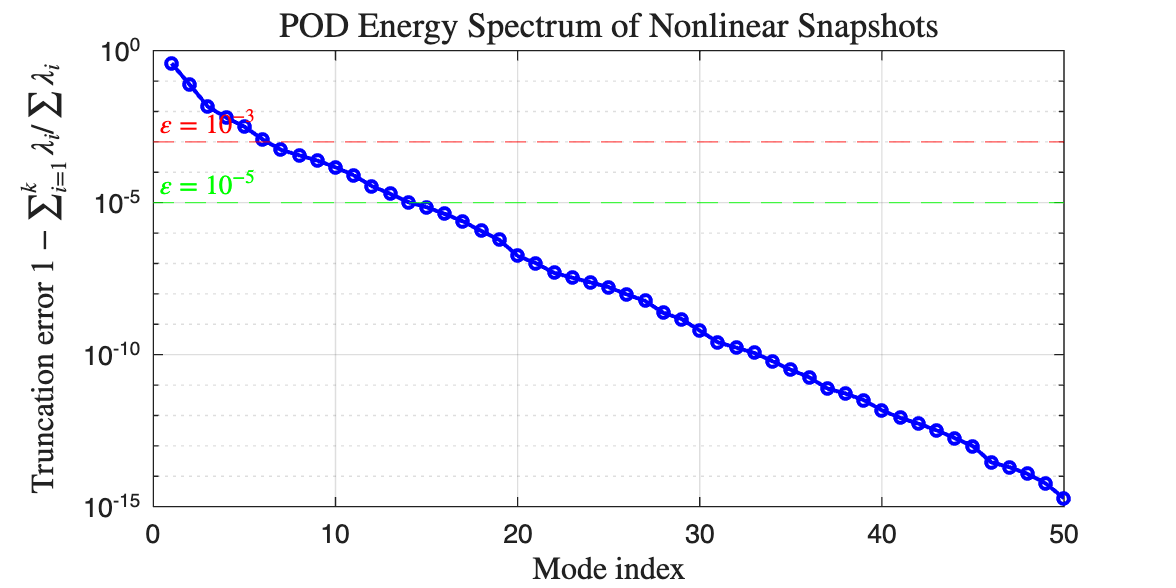


% plot energy decay
figure('Color','w','Position',[100 100 800 400]);
semilogy(1:min(50,length(lambda_sorted)), E_POD(1:min(50,end)), 'b-o', ...
    'MarkerSize', 4, 'LineWidth', 1.5);
grid on;
xlabel('Mode index', 'Interpreter','latex', 'FontSize', 12);
ylabel('Truncation error $1 - \sum_{i=1}^k \lambda_i / \sum \lambda_i$', ...
    'Interpreter','latex', 'FontSize', 12);
title('POD Energy Spectrum of Nonlinear Snapshots', 'Interpreter','latex', 'FontSize', 13);
yline(1e-3, 'r--', '$\varepsilon = 10^{-3}$', 'Interpreter','latex', 'LabelHorizontalAlignment','left');
yline(1e-5, 'g--', '$\varepsilon = 10^{-5}$', 'Interpreter','latex', 'LabelHorizontalAlignment','left');

%% Step 1 — Build V and V_bar from full snapshot set
k_prim = 6;
k_bar  = 14;

w_ref      = mean(w, 2);
W_centered = w - w_ref;

% reuse V_full from diagnostic block
V_prim = V_full(:, 1:k_prim);           % N_int x 6  (primary)
V_bar  = V_full(:, k_prim+1:k_prim+k_bar);  % N_int x 14 (secondary)

fprintf('V      size: [%d x %d]\n', size(V_prim));

V      size: [5329 x 6]


fprintf('V_bar  size: [%d x %d]\n', size(V_bar));

V_bar  size: [5329 x 14]



% verify orthogonality
assert(max(abs(V_prim'*V_bar), [], 'all') < 1e-8, 'V and V_bar not orthogonal');
fprintf('Orthogonality check passed.\n');

Orthogonality check passed.



%% Step 2 — Compute latent coordinates for all snapshots
fprintf('\nComputing latent coordinates...\n');


Computing latent coordinates...



q_all    = V_prim' * W_centered;   % k     x N_mu
q_bar_all = V_bar'  * W_centered;  % k_bar x N_mu

fprintf('q     size: [%d x %d]\n', size(q_all));

q     size: [6 x 1000]


fprintf('q_bar size: [%d x %d]\n', size(q_bar_all));

q_bar size: [14 x 1000]



% sanity check: reconstruction error with both bases
w_recon   = w_ref + V_prim * q_all + V_bar * q_bar_all;
recon_err = mean(vecnorm(w - w_recon) ./ vecnorm(w));
fprintf('Combined basis reconstruction error: %.2e\n', recon_err);

Combined basis reconstruction error: 1.12e-05



idx_tr = idx_lhs;        % same 10 LHS snapshots as DEIM (Part 3)
idx_te = idx_test;       % same 990 test points as DEIM (Part 3)

q_train     = q_all(:, idx_tr);       % k     x N_train
q_bar_train = q_bar_all(:, idx_tr);   % k_bar x N_train
q_test      = q_all(:, idx_te);
q_bar_test  = q_bar_all(:, idx_te);

%% Step 4 — Normalize inputs and outputs
q_mean = mean(q_train, 2);
q_std  = std(q_train, 0, 2) + 1e-8;

qb_mean = mean(q_bar_train, 2);
qb_std  = std(q_bar_train, 0, 2) + 1e-8;

normalize_q  = @(q)  (q  - q_mean)  ./ q_std;
normalize_qb = @(qb) (qb - qb_mean) ./ qb_std;
denorm_qb    = @(qb) qb .* qb_std + qb_mean;

q_tr_n  = normalize_q(q_train);
qb_tr_n = normalize_qb(q_bar_train);
q_te_n  = normalize_q(q_test);
qb_te_n = normalize_qb(q_bar_test);

%% Step 5 — Define and train ANN
% architecture: k -> 32 (tanh) -> k_bar
% with physics-informed quadratic skip connection

h = 32;  % hidden layer size

% we implement the quadratic skip manually via a custom training loop
% inputs:  q          (k x N_train)
% outputs: q_bar      (k_bar x N_train)

% convert to dlarray for deep learning toolbox
X_tr = dlarray(q_tr_n);
Y_tr = dlarray(qb_tr_n);
X_te = dlarray(q_te_n);
Y_te = dlarray(qb_te_n);

% initialize weights
rng(7);
W1 = dlarray(randn(h, k_prim)  * sqrt(2/k_prim));   % h x k
b1 = dlarray(zeros(h, 1));
W2 = dlarray(randn(k_bar, h)   * sqrt(2/h));         % k_bar x h
b2 = dlarray(zeros(k_bar, 1));
W3 = dlarray(randn(k_bar, k_prim) * 0.01);           % k_bar x k  (quadratic skip)

params.W1 = W1;  params.b1 = b1;
params.W2 = W2;  params.b2 = b2;
params.W3 = W3;

% training hyperparameters
lr         = 1e-3;
lambda_reg = 1e-4;
n_epochs   = 15000;
batch_size = 128;
N_tr       = size(q_tr_n, 2);

% Adam optimizer state
avg_grad  = [];
avg_sq_grad = [];
iter = 0;

fprintf('\nTraining ANN (%d epochs, batch=%d, lr=%.0e)...\n', n_epochs, batch_size, lr);


Training ANN (20000 epochs, batch=128, lr=1e-03)...


loss_hist = zeros(n_epochs, 1);
tic;
for epoch = 1:n_epochs
    % mini-batch
    idx_batch = randperm(N_tr, min(batch_size, N_tr));
    X_b = X_tr(:, idx_batch);
    Y_b = Y_tr(:, idx_batch);

    % compute loss and grads
    [loss, grads] = dlfeval(@annForwardLoss, params, X_b, Y_b, lambda_reg);
    loss_hist(epoch) = double(loss);

    % adam
    iter = iter + 1;
    [params, avg_grad, avg_sq_grad] = adamupdate(params, grads, ...
        avg_grad, avg_sq_grad, iter, lr);

    if mod(epoch, 200) == 0
        loss_te = dlfeval(@annForwardLoss, params, X_te, Y_te, 0);
        fprintf('  Epoch %4d  |  train loss: %.4e  |  test loss: %.4e\n', ...
            epoch, loss_hist(epoch), double(loss_te));
    end
end

  Epoch  200  |  train loss: 3.1770e+00  |  test loss: 3.8054e+01
  Epoch  400  |  train loss: 9.2512e-01  |  test loss: 5.0164e+01
  Epoch  600  |  train loss: 3.2317e-01  |  test loss: 5.9182e+01
  Epoch  800  |  train loss: 1.2009e-01  |  test loss: 6.3398e+01
  Epoch 1000  |  train loss: 4.5538e-02  |  test loss: 6.5009e+01
  Epoch 1200  |  train loss: 2.1346e-02  |  test loss: 6.5674e+01
  Epoch 1400  |  train loss: 1.4923e-02  |  test loss: 6.6001e+01
  Epoch 1600  |  train loss: 1.3544e-02  |  test loss: 6.6163e+01
  Epoch 1800  |  train loss: 1.3292e-02  |  test loss: 6.6235e+01
  Epoch 2000  |  train loss: 1.3237e-02  |  test loss: 6.6263e+01
  Epoch 2200  |  train loss: 1.3207e-02  |  test loss: 6.6274e+01
  Epoch 2400  |  train loss: 1.3177e-02  |  test loss: 6.6278e+01
  Epoch 2600  |  train loss: 1.3144e-02  |  test loss: 6.6281e+01
  Epoch 2800  |  train loss: 1.3108e-02  |  test loss: 6.6285e+01
  Epoch 3000  |  train loss: 1.3067e-02  |  test loss: 6.6290e+01
  Epoch 32

t_offline_ann = toc + (N_snap * t_hdm_per_solve);
fprintf('ANN training time: %.4f seconds\n', t_offline_ann);

ANN training time: 35.8923 seconds



% evaluate ANN on test set
fprintf('\nEvaluating ANN on test set...\n');


Evaluating ANN on test set...


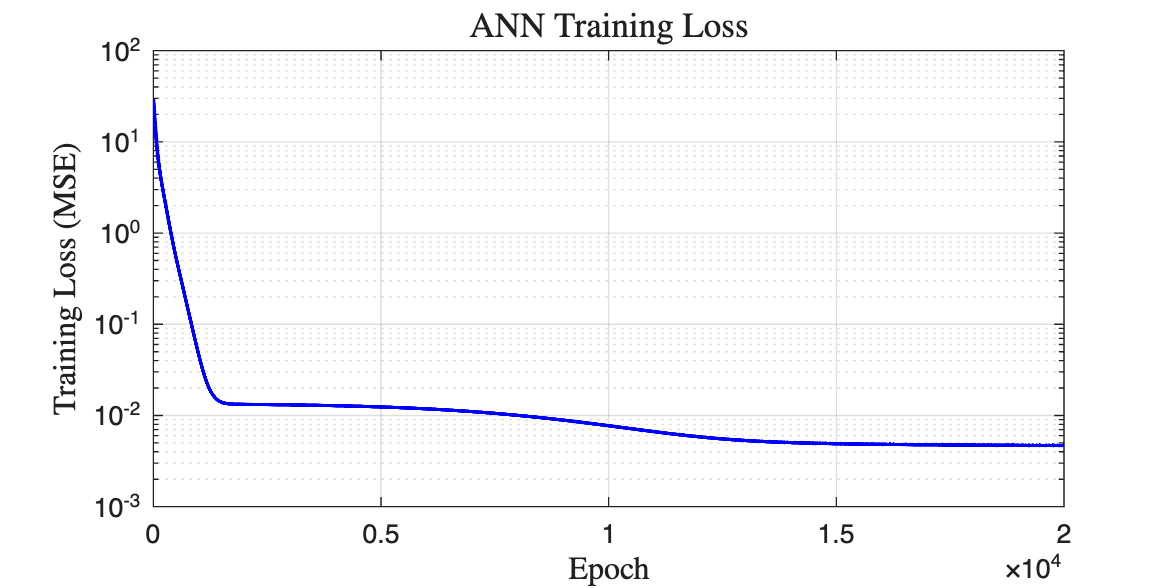

tic;
q_bar_pred_n = annForward(params, X_te);
q_bar_pred   = denorm_qb(double(extractdata(q_bar_pred_n)));
t_online_ann = toc;

% reconstruct full solutions
w_test_ann = w_ref + V_prim * q_test + V_bar * q_bar_pred;
% w_test_hdm = w(:, idx_te);

% errors_ann = computeErrors(w_test_hdm, w_test_ann);
% E_max_ann  = max(errors_ann);
% E_avg_ann  = mean(errors_ann);
% 
% fprintf('\n==================================================================\n');
% fprintf('ANN-Augmented PMOR results (%d test points):\n', length(idx_te));
% fprintf('E_max = %.4f\n', E_max_ann);
% fprintf('E_avg = %.4f\n', E_avg_ann);
% fprintf('==================================================================\n');

% plot training loss
figure('Color','w','Position',[100 100 800 400]);
semilogy(1:n_epochs, loss_hist, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('Epoch', 'Interpreter','latex', 'FontSize', 12);
ylabel('Training Loss (MSE)', 'Interpreter','latex', 'FontSize', 12);
title('ANN Training Loss', 'Interpreter','latex', 'FontSize', 13);


% vis one test case
j_vis    = 1;
T_hdm_v  = reshapeSolution(w_test(:,j_vis), Nx, Ny, T_D, y_values, mu(idx_te(j_vis),:));
T_ann_v  = reshapeSolution(w_test(:,j_vis), Nx, Ny, T_D, y_values, mu(idx_te(j_vis),:));

plotSolution(T_hdm_v,            mu(idx_te(j_vis),:), false);

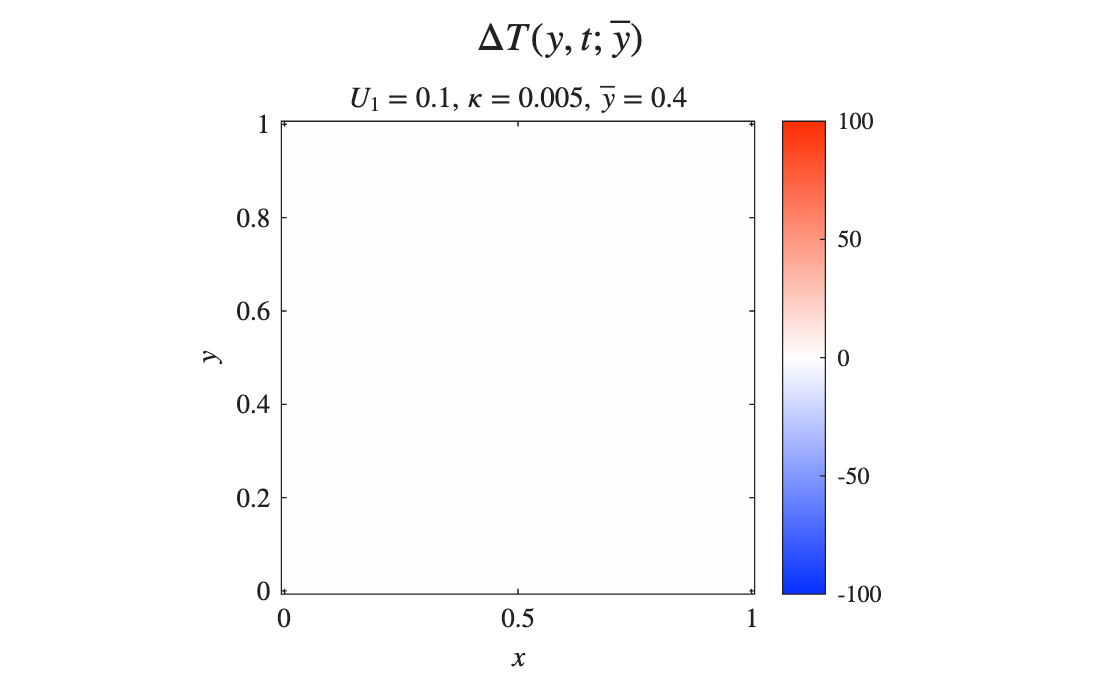

plotSolution(T_ann_v - T_hdm_v,  mu(idx_te(j_vis),:), true);

plotSolution(T_ann_v,            mu(idx_te(j_vis),:), false);

function q_bar_pred = annForward(params, X)
% forward pass:  linear -> tanh -> linear  +  quadratic skip
    Z1  = params.W1 * X + params.b1;        % h x N
    A1  = tanh(Z1);                          % h x N
    Z2  = params.W2 * A1 + params.b2;       % k_bar x N
    Xsq = X .* X;                            % quadratic skip: k x N
    q_bar_pred = Z2 + params.W3 * Xsq;      % k_bar x N
end

function [loss, grads] = annForwardLoss(params, X, Y, lambda_reg)
% MSE loss + L2 regularization
    Y_pred = annForward(params, X);
    N      = size(Y, 2);
    mse    = sum((Y_pred - Y).^2, 'all') / N;
    reg    = lambda_reg * (sum(params.W1.^2,'all') + ...
                           sum(params.W2.^2,'all') + ...
                           sum(params.W3.^2,'all'));
    loss   = mse + reg;
    grads  = dlgradient(loss, params);
end

## PROM Error Analysis

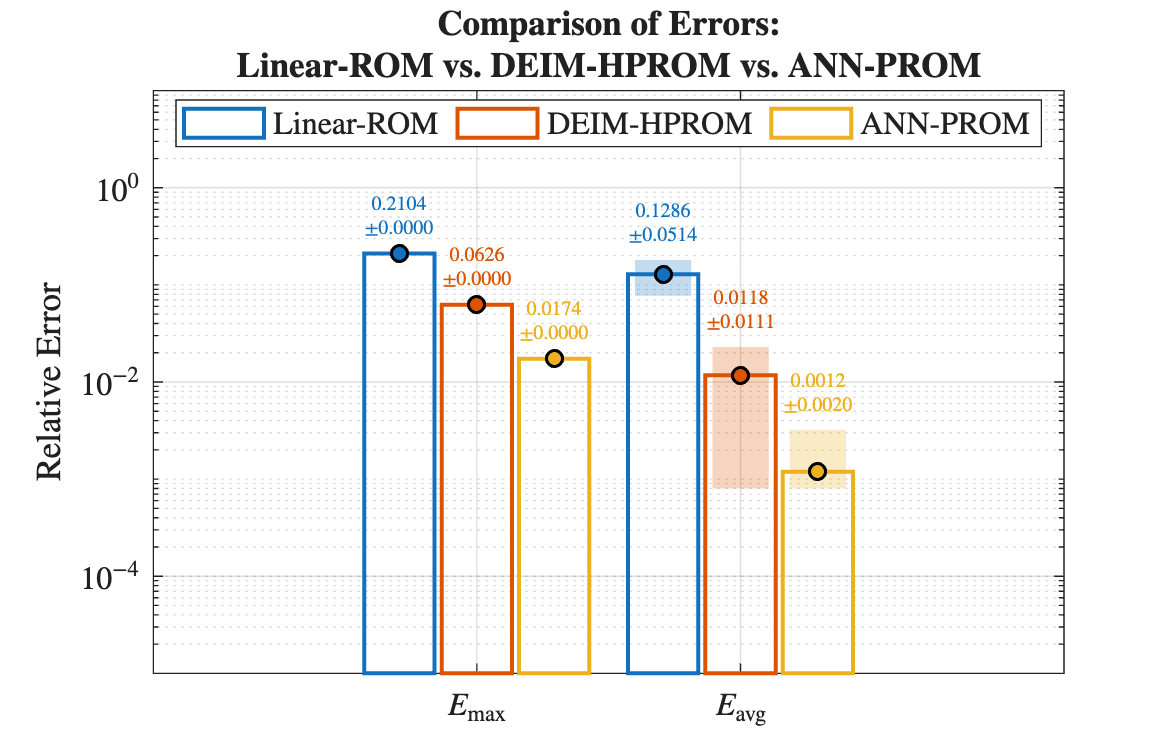

% STD Galerkin
errors_affine = computeErrors(w_test_k, w_r_k);
E_max_affine  = max(errors_affine);
E_avg_affine  = mean(errors_affine);

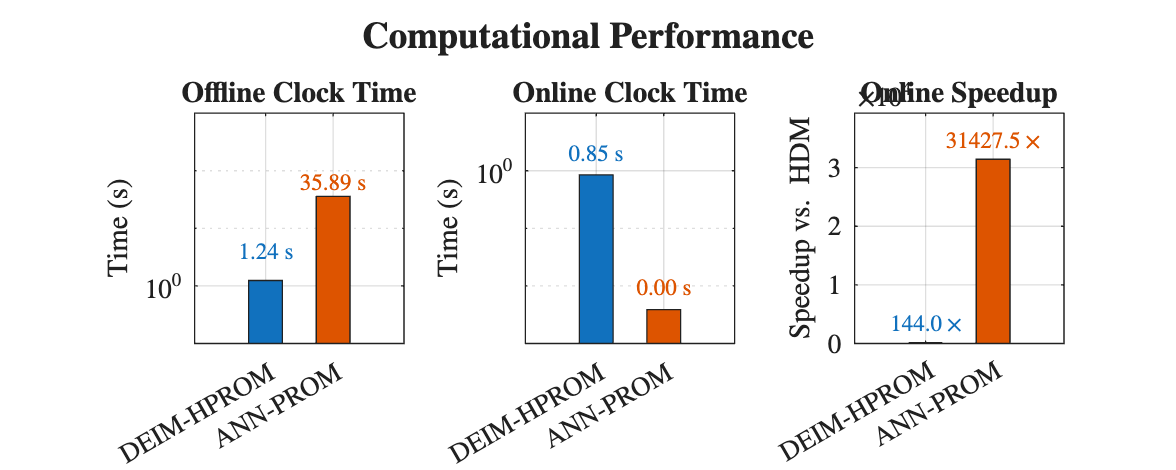

E_std_affine  = std(errors_affine);

% DEIM
errors_deim = computeErrors(w_test_hdm, w_r_deim);
E_max_deim  = max(errors_deim);
E_avg_deim  = mean(errors_deim);
E_std_deim  = std(errors_deim);

% ANN
errors_ann = computeErrors(w_test_hdm, w_test_ann);
E_max_ann  = max(errors_ann);
E_avg_ann  = mean(errors_ann);
E_std_ann  = std(errors_ann);

means = [E_max_affine,  E_max_deim,  E_max_ann;

         E_avg_affine,  E_avg_deim,  E_avg_ann];

stdevs = [0,             0,           0;
          E_std_affine,  E_std_deim,  E_std_ann];

plotErrorComparison(means, stdevs, {'Linear-ROM', 'DEIM-HPROM', 'ANN-PROM'}, true);

## PROM Computational Cost Analysis

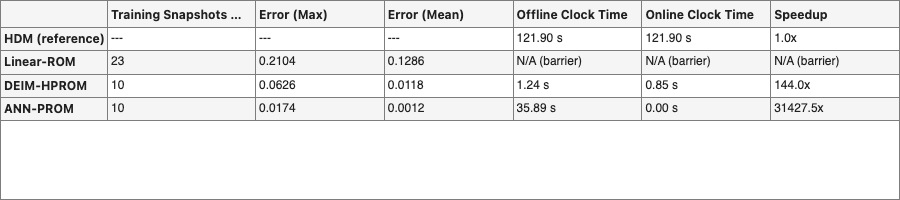

%% Final Summary Table Figure
t_hdm_per = time_HDM / N_mu;
t_hdm_cum = t_hdm_per * 990;

speedup_deim = t_hdm_cum / t_online_deim;
speedup_ann  = t_hdm_cum / t_online_ann;

times_offline = [t_offline_deim, t_offline_ann];
times_online  = [t_online_deim,  t_online_ann];
speedups      = [speedup_deim,   speedup_ann];

plotTimeComparison(times_offline, times_online, speedups, ...
    {'DEIM-HPROM', 'ANN-PROM'});

Method    = ["HDM (ref.)"; ...
             sprintf("Linear-ROM"); ...
             sprintf("DEIM-HPROM"); ...
             sprintf("ANN-PROM")];

Snapshots = ["---"; sprintf("%d", k_plateau); sprintf("%d", N_snap); sprintf("%d", N_snap)];
E_max_col = ["---"; sprintf("%.4f", E_max_affine); sprintf("%.4f", E_max_deim); sprintf("%.4f", E_max_ann)];
E_avg_col = ["---"; sprintf("%.4f", E_avg_affine); sprintf("%.4f", E_avg_deim); sprintf("%.4f", E_avg_ann)];
Offline_s = [sprintf("%.2f s", t_hdm_cum); "N/A (barrier)"; sprintf("%.2f s", t_offline_deim); sprintf("%.2f s", t_offline_ann)];
Online_s  = [sprintf("%.2f s", t_hdm_cum); "N/A (barrier)"; sprintf("%.2f s", t_online_deim);  sprintf("%.2f s", t_online_ann)];
Speedup   = ["---"; "N/A (barrier)"; sprintf("%.1fx", speedup_deim); sprintf("%.1fx", speedup_ann)];

T = table(Snapshots, E_max_col, E_avg_col, Offline_s, Online_s, Speedup, ...
    'RowNames',       cellstr(Method), ...
    'VariableNames',  {'No. Snapshots (k)','Error (Max)','Error (Mean)','Offline Clock Time','Online Clock Time','Speedup'});

fig = uifigure('Name', 'ROM Performance Summary', 'Position', [100 100 900 200]);
uitable(fig, 'Data', T, 'Units', 'Normalized', 'Position', [0 0 1 1]);